# **Projet : Introduction à la mécanique spatiale **

**Boris Baudel**

**PS : Le script fournit le code ainsi que les résultats numériques globaux. Pour les réponses détaillées à chaque question, veuillez vous référer au rapport.**

# **Exercice II  : **

Un véhicule spatial décrit une orbite circulaire avec une altitude de 500 km. Il doit effectuer un rendezvous avec un autre véhicule spatial (appelé véhicule cible) qui décrit une orbite circulaire à une altitude de 1500 km. On donne : masse =2000kg, Isp=1000s. 

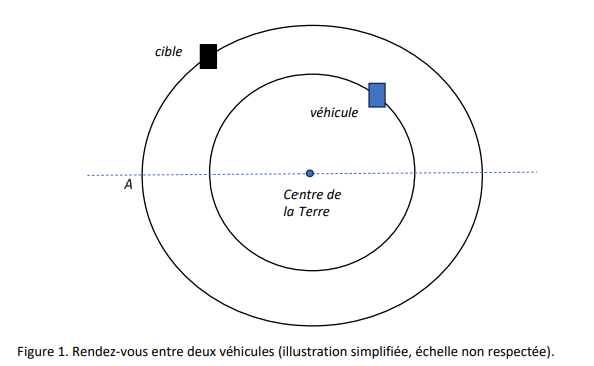

# Partie 1 : Transfert sans rendez-vous avec la cible

**Question 1 : **

Le véhicule évolue initialement sur une orbite circulaire d’altitude h1 et doit rejoindre une orbite circulaire à 

h2 sans se synchroniser avec la cible.  Le transfert optimal dans ce cas est un transfert de Hohmann.

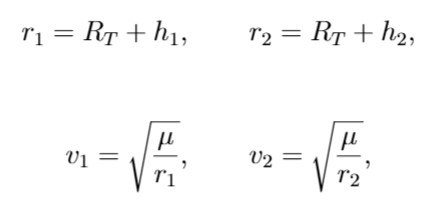

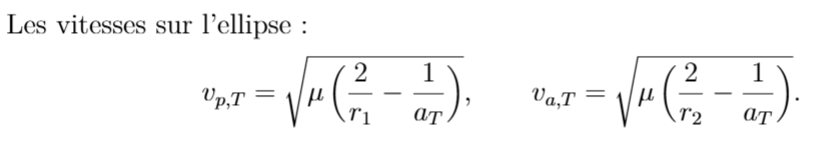

clear; clc;

% --- Constantes ---
mu  = 3.986004418e14;   % [m^3/s^2] paramètre gravitationnel Terre
Re  = 6371e3;           % [m] rayon moyen de la Terre

% --- Données de l'exercice ---
h1  = 500e3;            % [m] altitude orbite initiale
h2  = 1500e3;           % [m] altitude orbite cible
m0  = 2000;             % [kg] masse du véhicule
Isp = 1000;             % [s] impulsion spécifique (si besoin plus tard)
g0  = 9.80665;          % [m/s^2]

% --- Rayons orbitaux ---
r1 = Re + h1;           % [m]
r2 = Re + h2;           % [m]

% Vitesses sur les orbites circulaires
v1 = sqrt(mu/r1);       % [m/s] orbite basse
v2 = sqrt(mu/r2);       % [m/s] orbite haute

% --- Ellipse de transfert de Hohmann ---
aT   = (r1 + r2)/2;                     % [m] demi-grand axe de l'ellipse
vP_T = sqrt(mu*(2/r1 - 1/aT));          % [m/s] vitesse à périgée (point B)
vA_T = sqrt(mu*(2/r2 - 1/aT));          % [m/s] vitesse à apogée (point A)

% Incréments de vitesse (impulsions) :
dV1 = vP_T - v1;                        % [m/s] impulsion au point B
dV2 = v2   - vA_T;                      % [m/s] impulsion au point A
dVtot = dV1 + dV2;

% Durée du transfert = demi-période de l'ellipse
Ttrans = pi*sqrt(aT^3/mu);              % [s]
Ttrans_min = Ttrans/60;                 % [min]

% --- Affichage des résultats ---
fprintf('Transfert de Hohmann 500 km -> 1500 km\n');

Transfert de Hohmann 500 km -> 1500 km


fprintf('dV1 (point B, prograde) = %.1f m/s\n', dV1);

dV1 (point B, prograde) = 254.1 m/s


fprintf('dV2 (point A, prograde) = %.1f m/s\n', dV2);

dV2 (point A, prograde) = 245.6 m/s


fprintf('dV total                = %.1f m/s\n', dVtot);

dV total                = 499.7 m/s


fprintf('Durée du transfert      = %.1f s (%.2f min)\n', Ttrans, Ttrans_min);

Durée du transfert      = 3149.0 s (52.48 min)


#### **Bonus  : Tracé du transfert **

% --- Orbites circulaires ---
theta = linspace(0,2*pi,400);
x1 = r1*cos(theta);   y1 = r1*sin(theta);   % orbite basse
x2 = r2*cos(theta);   y2 = r2*sin(theta);   % orbite haute

% --- Ellipse de transfert de Hohmann ---
aT = (r1 + r2)/2;
eT = (r2 - r1)/(r2 + r1);      % excentricité

nu = linspace(0,pi,300);       % de B (perigée) vers A (apogée)
p  = aT*(1 - eT^2);
r  = p ./ (1 + eT*cos(nu));
xT = r .* cos(nu);
yT = r .* sin(nu);

% --- Points clés : B (périgée) et A (apogée) ---
% ici : B à droite, A à gauche, pour coller au schéma classique
nuB = 0;                       % périgée
nuA = pi;                      % apogée
rB  = p/(1 + eT*cos(nuB));     % = r1
rA  = p/(1 + eT*cos(nuA));     % = r2

xB = rB*cos(nuB); yB = rB*sin(nuB);
xA = rA*cos(nuA); yA = rA*sin(nuA);

% --- Directions de vitesse (pour les flèches Δv) ---
% Sur une orbite circulaire, vitesse tangentielle et perpendiculaire au rayon
% B : à droite (x>0), vitesse vers le haut (sens anti-horaire)
dirB = [0 1];      % direction de la flèche Δv1 (vers +y)
% A : à gauche (x<0), vitesse vers le haut également
dirA = [0 1];      % direction de la flèche Δv2

scale = 0.1*r1;    % longueur visuelle des flèches

% --- Tracé ---
figure; hold on; axis equal;
grid on; box on;

% Terre
plot(0,0,'ko','MarkerFaceColor','k','MarkerSize',6);
text(0,0,'  Terre','VerticalAlignment','bottom');

% Orbites circulaires
plot(x1,y1,'b-','LineWidth',1.2);
plot(x2,y2,'k-','LineWidth',1.2);

% Ellipse de transfert
plot(xT,yT,'r--','LineWidth',1.5);

% Points A et B
plot(xB,yB,'bo','MarkerFaceColor','b','MarkerSize',6);
text(xB,yB,'  B','VerticalAlignment','bottom');

plot(xA,yA,'ks','MarkerFaceColor','k','MarkerSize',6);
text(xA,yA,'  A','VerticalAlignment','bottom');

% Flèches de ∆v
quiver(xB,yB,scale*dirB(1),scale*dirB(2),0,'b','LineWidth',1.5,...
       'MaxHeadSize',0.8);
text(xB+0.05*r1,yB+0.15*r1,'\Delta v_1','Color','b');

quiver(xA,yA,scale*dirA(1),scale*dirA(2),0,'r','LineWidth',1.5,...
       'MaxHeadSize',0.8);
text(xA+0.05*r1,yA+0.15*r1,'\Delta v_2','Color','r');

xlabel('x [m]');
ylabel('y [m]');
title('Transfert de Hohmann 500 km \rightarrow 1500 km');

legend({'Orbite basse','Orbite haute','Ellipse de transfert'},...
       'Location','bestoutside');

# **Partie 2 : Transfert sans rendez-vous avec la cible**

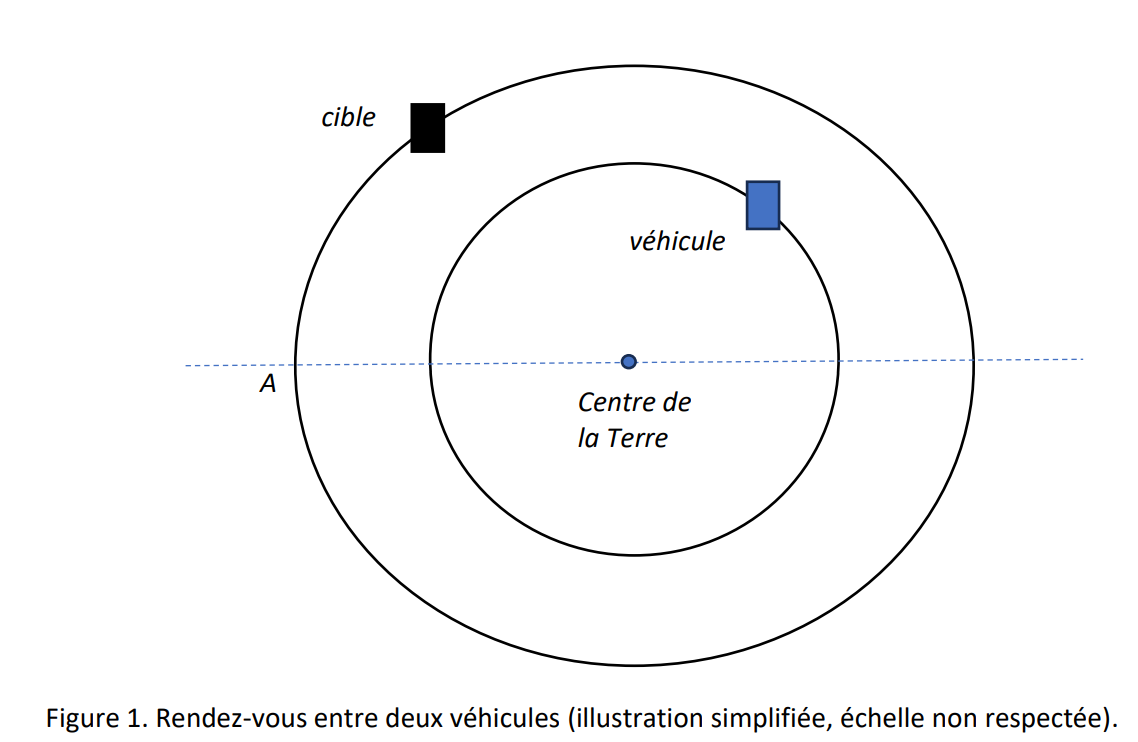

**Question 1-2-3) : **

Dans la Partie 1, le véhicule effectue un transfert de Hohmann de l’orbite basse (h1=500km) vers l’orbite haute (h2= 1500km), sans se soucier de la position du véhicule cible.Pour réaliser un rendez-vous, il faut conserver le même transfert de Hohmann (mêmes impulsions ∆v1, ∆v2) mais déclencher la première impulsion plus tard, lorsque la cible se trouve àune position angulaire telle que, pendant le temps de transfert, elle parvienne aupoint de rendez-vous (ici le point A).

On introduit donc une phase d’attente sur l’orbite basse

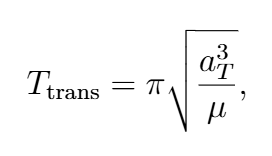

%% Exercice 2 - Transfert de Hohmann avec rendez-vous
clear; clc;

%% --- Constantes physiques ---
Re   = 6371e3;        % Rayon terrestre [m]
mu   = 3.986e14;      % Paramètre gravitationnel Terre [m^3/s^2]
g0   = 9.81;          % Gravité au sol [m/s^2]

%% --- Données du problème ---
h1   = 500e3;         % Altitude orbite basse [m]
h2   = 1500e3;        % Altitude orbite haute [m]
m0   = 2000;          % Masse initiale [kg]
Isp  = 1000;          % Impulsion spécifique [s]

% Rayons orbitaux
r1   = Re + h1;       % [m]
r2   = Re + h2;       % [m]

%% --- Orbite de transfert de Hohmann ---
a_t  = (r1 + r2)/2;                        % Demi-grand axe [m]

% Temps de transfert (périgée -> apogée = demi-orbite)
t_trans = pi * sqrt(a_t^3 / mu);          % [s]
t_trans_min = t_trans / 60;               % [min]

%% --- Mouvement de la cible sur l'orbite haute ---
n2   = sqrt(mu / r2^3);                   % Vitesse angulaire [rad/s]
dtheta_cible = n2 * t_trans;              % Angle parcouru pendant le transfert

% Condition de rendez-vous :
% véhicule arrive à l'apogée (π rad du point A sur l'orbite de départ)
% phi0 + n2*t_trans = pi  =>  phi0 = pi - n2*t_trans
phi0 = pi - dtheta_cible;                 % [rad]
phi0_deg = phi0 * 180/pi;                 % [deg]

%% --- Delta-V du Hohmann ---
% Vitesses circulaires
v1   = sqrt(mu / r1);                     % Vitesse orbite basse [m/s]
v2   = sqrt(mu / r2);                     % Vitesse orbite haute [m/s]

% Vitesses sur l'ellipse de transfert
v_peri = sqrt(mu * (2/r1 - 1/a_t));       % Vitesse à périgée de l'ellipse [m/s]
v_apo  = sqrt(mu * (2/r2 - 1/a_t));       % Vitesse à apogée de l'ellipse [m/s]

% Impulsions
dV1 = v_peri - v1;                        % [m/s]
dV2 = v2 - v_apo;                         % [m/s]
dV_tot = dV1 + dV2;                       % [m/s]

%% --- Équation de Tsiolkovski : masse d'ergols ---
mr    = exp(dV_tot / (Isp * g0));         % Rapport m0/mf
mf    = m0 / mr;                          % Masse finale [kg]
m_prop = m0 - mf;                         % Masse d'ergols consommée [kg]

%% --- Affichage des résultats ---
fprintf('--- Transfert de Hohmann avec rendez-vous ---\n');

--- Transfert de Hohmann avec rendez-vous ---


fprintf('Rayon orbite basse r1      = %.0f km\n', r1/1e3);

Rayon orbite basse r1      = 6871 km


fprintf('Rayon orbite haute r2      = %.0f km\n', r2/1e3);

Rayon orbite haute r2      = 7871 km


fprintf('Demi-grand axe a_t         = %.0f km\n', a_t/1e3);

Demi-grand axe a_t         = 7371 km


fprintf('\n');

fprintf('Temps de transfert t_trans = %.1f s (%.2f min)\n', t_trans, t_trans_min);

Temps de transfert t_trans = 3149.0 s (52.48 min)


fprintf('Vitesse angulaire n2       = %.4e rad/s\n', n2);

Vitesse angulaire n2       = 9.0412e-04 rad/s


fprintf('Angle cible pendant transit= %.2f deg\n', dtheta_cible*180/pi);

Angle cible pendant transit= 163.12 deg


fprintf('Angle initial cible phi0   = %.3f rad (%.2f deg)\n', phi0, phi0_deg);

Angle initial cible phi0   = 0.295 rad (16.88 deg)


fprintf('\n');

fprintf('Delta-V1 (orbite basse -> ellipse) = %.1f m/s\n', dV1);

Delta-V1 (orbite basse -> ellipse) = 254.1 m/s


fprintf('Delta-V2 (ellipse -> orbite haute) = %.1f m/s\n', dV2);

Delta-V2 (ellipse -> orbite haute) = 245.6 m/s


fprintf('Delta-V total                        = %.1f m/s\n', dV_tot);

Delta-V total                        = 499.7 m/s


fprintf('\n');

fprintf('Masse initiale        m0 = %.1f kg\n', m0);

Masse initiale        m0 = 2000.0 kg


fprintf('Masse finale          mf = %.1f kg\n', mf);

Masse finale          mf = 1900.7 kg


fprintf('Masse d''ergols consommée  = %.1f kg\n', m_prop);

Masse d'ergols consommée  = 99.3 kg



%% Exercice 2 - Transfert de Hohmann avec rendez-vous + trajectoire
clear; clc; close all;

%% --- Constantes physiques ---
Re   = 6371e3;        % Rayon terrestre [m]
mu   = 3.986e14;      % Paramètre gravitationnel Terre [m^3/s^2]
g0   = 9.81;          % Gravité au sol [m/s^2]

%% --- Données du problème ---
h1   = 500e3;         % Altitude orbite basse [m]
h2   = 1500e3;        % Altitude orbite haute [m]
m0   = 2000;          % Masse initiale [kg]
Isp  = 1000;          % Impulsion spécifique [s]

% Rayons orbitaux
r1   = Re + h1;       % [m]
r2   = Re + h2;       % [m]

%% --- Orbite de transfert de Hohmann ---
a_t  = (r1 + r2)/2;                        % Demi-grand axe [m]
e_t  = (r2 - r1)/(r1 + r2);               % Excentricité de l'ellipse de transfert

% Temps de transfert (périgée -> apogée = demi-orbite)
t_trans = pi * sqrt(a_t^3 / mu);          % [s]
t_trans_min = t_trans / 60;               % [min]

%% --- Mouvement de la cible sur l'orbite haute ---
n2   = sqrt(mu / r2^3);                   % Vitesse angulaire [rad/s]
dtheta_cible = n2 * t_trans;              % Angle parcouru pendant le transfert

% Condition de rendez-vous :
% véhicule arrive à l'apogée (π rad du point A sur l'orbite de départ)
% phi0 + n2*t_trans = pi  =>  phi0 = pi - n2*t_trans
phi0 = pi - dtheta_cible;                 % [rad]
phi0_deg = phi0 * 180/pi;                 % [deg]

%% --- Delta-V du Hohmann ---
% Vitesses circulaires
v1   = sqrt(mu / r1);                     % Vitesse orbite basse [m/s]
v2   = sqrt(mu / r2);                     % Vitesse orbite haute [m/s]

% Vitesses sur l'ellipse de transfert
v_peri = sqrt(mu * (2/r1 - 1/a_t));       % Vitesse à périgée de l'ellipse [m/s]
v_apo  = sqrt(mu * (2/r2 - 1/a_t));       % Vitesse à apogée de l'ellipse [m/s]

% Impulsions
dV1 = v_peri - v1;                        % [m/s]
dV2 = v2 - v_apo;                         % [m/s]
dV_tot = dV1 + dV2;                       % [m/s]

%% --- Équation de Tsiolkovski : masse d'ergols ---
mr    = exp(dV_tot / (Isp * g0));         % Rapport m0/mf
mf    = m0 / mr;                          % Masse finale [kg]
m_prop = m0 - mf;                         % Masse d'ergols consommée [kg]

%% --- Affichage des résultats numériques (console) ---
fprintf('--- Transfert de Hohmann avec rendez-vous ---\n');

--- Transfert de Hohmann avec rendez-vous ---


fprintf('Rayon orbite basse r1      = %.0f km\n', r1/1e3);

Rayon orbite basse r1      = 6871 km


fprintf('Rayon orbite haute r2      = %.0f km\n', r2/1e3);

Rayon orbite haute r2      = 7871 km


fprintf('Demi-grand axe a_t         = %.0f km\n', a_t/1e3);

Demi-grand axe a_t         = 7371 km


fprintf('\n');

fprintf('Temps de transfert t_trans = %.1f s (%.2f min)\n', t_trans, t_trans_min);

Temps de transfert t_trans = 3149.0 s (52.48 min)


fprintf('Vitesse angulaire n2       = %.4e rad/s\n', n2);

Vitesse angulaire n2       = 9.0412e-04 rad/s


fprintf('Angle cible pendant transit= %.2f deg\n', dtheta_cible*180/pi);

Angle cible pendant transit= 163.12 deg


fprintf('Angle initial cible phi0   = %.3f rad (%.2f deg)\n', phi0, phi0_deg);

Angle initial cible phi0   = 0.295 rad (16.88 deg)


fprintf('\n');

fprintf('Delta-V1 (basse -> ellipse) = %.1f m/s\n', dV1);

Delta-V1 (basse -> ellipse) = 254.1 m/s


fprintf('Delta-V2 (ellipse -> haute) = %.1f m/s\n', dV2);

Delta-V2 (ellipse -> haute) = 245.6 m/s


fprintf('Delta-V total               = %.1f m/s\n', dV_tot);

Delta-V total               = 499.7 m/s


fprintf('\n');

fprintf('Masse initiale        m0 = %.1f kg\n', m0);

Masse initiale        m0 = 2000.0 kg


fprintf('Masse finale          mf = %.1f kg\n', mf);

Masse finale          mf = 1900.7 kg


fprintf('Masse d''ergols consommée  = %.1f kg\n', m_prop);

Masse d'ergols consommée  = 99.3 kg


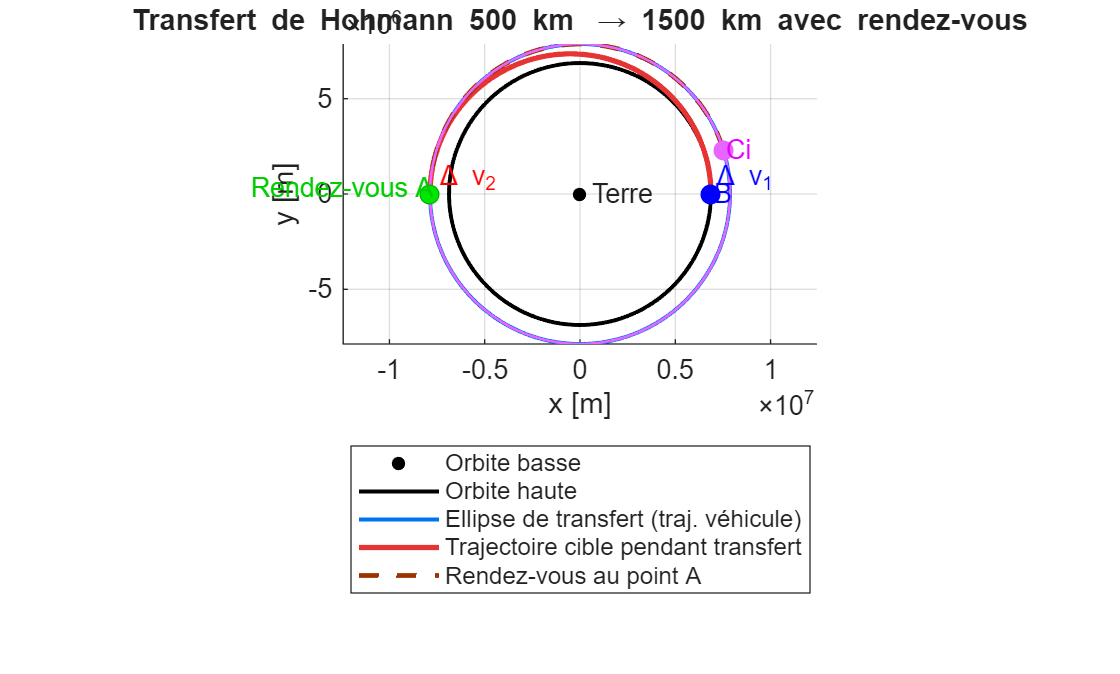

%% Transfert de Hohmann 500 km -> 1500 km avec rendez-vous : TRAJECTOIRE
clear; clc; close all;

%% --- Constantes ---
Re   = 6371e3;        % Rayon Terre [m]
mu   = 3.986e14;      % [m^3/s^2]
g0   = 9.81;          % [m/s^2]

%% --- Données ---
h1   = 500e3;         % orbite basse [m]
h2   = 1500e3;        % orbite haute [m]
m0   = 2000;          % masse [kg]
Isp  = 1000;          % [s]

r1 = Re + h1;         % rayon orbite basse [m]
r2 = Re + h2;         % rayon orbite haute [m]

%% --- Hohmann + phasage ---
a_t = (r1 + r2)/2;                     % demi-grand axe [m]
e_t = (r2 - r1)/(r1 + r2);            % excentricité

t_trans = pi * sqrt(a_t^3/mu);        % temps de transfert (demi-orbite) [s]
n2      = sqrt(mu/r2^3);              % vitesse angulaire cible [rad/s]
theta_arc = n2 * t_trans;             % angle parcouru par la cible pendant t_trans

% Rendez-vous au point A (côté gauche)
theta_A  = pi;                        % [rad]
% position initiale de la cible Ci : derrière A de theta_arc
theta_Ci = theta_A - theta_arc;       % [rad]
theta_B  = 0;                         % point B à droite (départ véhicule)

%% --- Courbes en coordonnées XY (m) ---
theta = linspace(0, 2*pi, 800);

% Orbite basse
x1 = r1 * cos(theta);
y1 = r1 * sin(theta);

% Orbite haute
x2 = r2 * cos(theta);
y2 = r2 * sin(theta);

% Ellipse de transfert (périgée à B, apogée à A)
theta_tr = linspace(theta_B, theta_A, 400);
r_tr = a_t*(1 - e_t^2) ./ (1 + e_t*cos(theta_tr));   % r(θ)
x_tr = r_tr .* cos(theta_tr);
y_tr = r_tr .* sin(theta_tr);

% Trajectoire de la cible pendant le transfert (arc Ci -> A)
theta_c_arc = linspace(theta_Ci, theta_A, 200);
x_c_arc = r2 * cos(theta_c_arc);
y_c_arc = r2 * sin(theta_c_arc);

%% --- Points particuliers ---
% B : départ véhicule
xB = r1 * cos(theta_B);   yB = r1 * sin(theta_B);
% Rendez-vous A (même angle, rayon r2)
xA = r2 * cos(theta_A);   yA = r2 * sin(theta_A);
% Cible au temps initial Ci
xCi = r2 * cos(theta_Ci); yCi = r2 * sin(theta_Ci);

%% --- Figure ---
figure('Name','Transfert de Hohmann 500 km -> 1500 km avec rendez-vous');
hold on; grid on; axis equal;

% Terre
plot(0, 0, 'k.', 'MarkerSize', 15);
text(0.1*Re, 0, 'Terre', 'HorizontalAlignment','left');

% Orbite basse
plot(x1, y1, 'k', 'LineWidth', 1.5);

% Orbite haute
plot(x2, y2, 'Color',[0 0.45 0.95], 'LineWidth', 1.5);

% Ellipse de transfert (traj. véhicule)
plot(x_tr, y_tr, 'Color',[0.9 0.2 0.2], 'LineWidth', 2);

% Trajectoire de la cible pendant le transfert
plot(x_c_arc, y_c_arc, '--', 'Color',[0.6 0.2 0], 'LineWidth', 1.8);

% Position initiale de la cible Ci (arc magenta)
plot(x2, y2, 'Color',[0.9 0.4 1], 'LineWidth', 1);  % orbite cible en magenta clair
plot(xCi, yCi, 'o', 'MarkerEdgeColor',[0.9 0.4 1], ...
               'MarkerFaceColor',[0.9 0.4 1], 'MarkerSize', 7);
text(xCi*1.02, yCi, 'Ci', 'Color',[0.9 0.0 1]);

% Point B (départ)
plot(xB, yB, 'o', 'MarkerEdgeColor','b', 'MarkerFaceColor','b', 'MarkerSize', 7);
text(xB*1.02, yB, 'B', 'Color','b');

% Point de rendez-vous A
plot(xA, yA, 'o', 'MarkerEdgeColor',[0 0.7 0], ...
               'MarkerFaceColor',[0 0.9 0], 'MarkerSize', 7);
text(xA*0.98, yA+0.3e6, 'Rendez-vous A', 'Color',[0 0.8 0], ...
     'HorizontalAlignment','right');

% Indication des Δv
text(xB*1.02, yB+0.8e6, '\Delta v_1', 'Color','b');
text(xA*0.95, yA+0.8e6, '\Delta v_2', 'Color',[1 0 0]);

% Axes
xlabel('x [m]');
ylabel('y [m]');
title('Transfert de Hohmann 500 km \rightarrow 1500 km avec rendez-vous');

% Un petit facteur 10^6 sur les axes pour les graduations
set(gca,'DataAspectRatio',[1 1 1]);

% Légende
legend({'Orbite basse', ...
        'Orbite haute', ...
        'Ellipse de transfert (traj. véhicule)', ...
        'Trajectoire cible pendant transfert', ...
        'Rendez-vous au point A'}, ...
        'Location','southoutside','Orientation','vertical');

hold off;

# **Partie 3 : Transfert avec rendez-vous avec la cible **

On suppose que l’on a effectué le transfert vers l’orbite cible, sans se préoccuper du rendez-vous (transfert étudié à la partie 1 de ce problème). Après le transfert, le véhicule se retrouve sur l’orbite cible mais à une position sur l’orbite différente de celle de la cible. Nous considérons deux cas de figures (voir Figure 2).

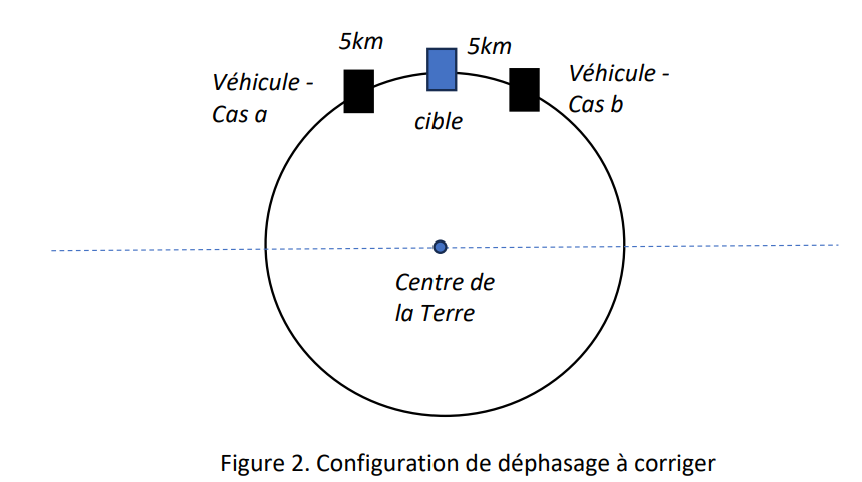

**Question 1 :  Ecart entre le véhicule et la cible en termes d’erreur en anomalie vraie et d’écart temporel à corriger**

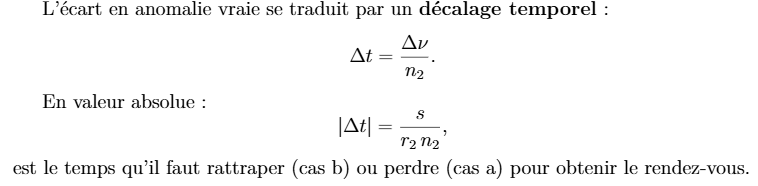


T2 = 2*pi / n2;   % période orbitale de l'orbite haute
s_arc = 5e3;                % [m] décalage le long de l'orbite

% 1) Erreur en anomalie vraie et temps
Delta_nu = s_arc / r2;      % [rad]
Delta_t  = Delta_nu / n2;   % [s]

fprintf('Delta_nu = %.3e rad (%.3f deg)\n', ...
        Delta_nu, Delta_nu*180/pi);

Delta_nu = 6.352e-04 rad (0.036 deg)


fprintf('Delta_t  = %.2f s (%.2f min)\n', ...
        Delta_t, Delta_t/60);

Delta_t  = 0.70 s (0.01 min)


**Question 2 : **

Première poussée tangentielle au point courant (par exemple au pointA) : onquitte l’orbite circulaire de rayon r2pour une orbite de phasage (ellipse coplanaire)de demi-grand axeap, choisie de sorte que sa périodeTpsoit différente de celle del’orbite cible T2juste ce qu’il faut pour corriger le déphasage.La période de l’orbite cible est : 

On choisit une orbite de phasage de période

Cas a (véhicule en avance) : on veut que le véhicule avance moins vite quela cible pour se faire rattraper, donc on choisit une orbite plus haute (périodeplus longue) : 

Cas b (véhicule en retard) : on veut que le véhicule avance plus vite que lacible pour la rattraper, donc on choisit une orbite plus basse (période pluscourte) :

**Question 3 :**

On note toujourss= 5kmla longueur d’arc séparant le véhicule de la cible surl’orbite circulaire haute de rayon r2.

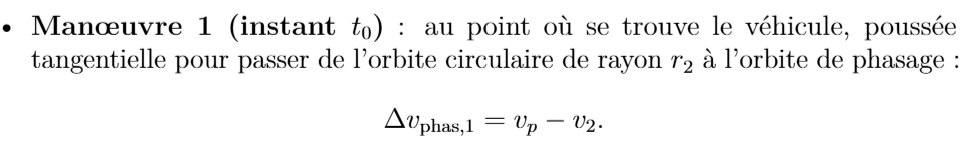

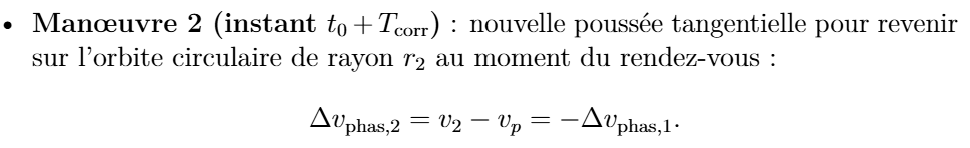

% --- Cas a : véhicule en avance => orbite plus haute (periode plus longue)
Tp_a = T2 + abs(Delta_t);               % [s]
ap_a = (mu*(Tp_a/(2*pi))^2)^(1/3);      % [m]
r_other_a = 2*ap_a - r2;

v2    = sqrt(mu/r2);                    % [m/s] vitesse circulaire
vp_a  = sqrt(mu*(2/r2 - 1/ap_a));       % [m/s] vitesse ellipse phasage au point de depart
dV1_a = vp_a - v2;                      % impulsion 1 cas a
dV2_a = -dV1_a;                         % retour à la circulaire (même point)

fprintf('Cas a (vehicule en avance): ap = %.3e m, dV1 = %.2f m/s\n', ...
        ap_a, dV1_a);

Cas a (vehicule en avance): ap = 7.872e+06 m, dV1 = 0.24 m/s


**Question 4 : **

On reprend les mêmes formules en remplaçant Tcorrpar 5 h et 15 h

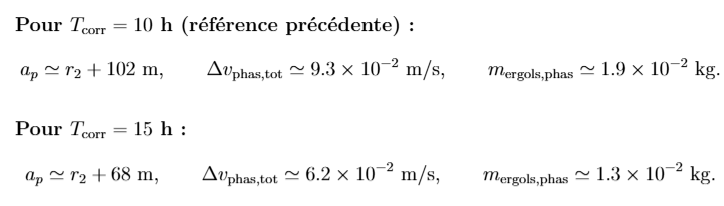

phasage = @(Tcorr, sign_phase) deal( ...
    ... n_p :
    sqrt(mu ./ ((mu ./ ( (n2 - sign_phase*Delta_nu./Tcorr).^2 )).^(1/3).^3)), ...
    ... a_p :
    (mu ./ ( (n2 - sign_phase*Delta_nu./Tcorr).^2 )).^(1/3) );

% petite fonction plus lisible :
function [a_p, dV1, dV2, dVtot, m_prop] = phasage_simple(Tcorr, sign_phase, ...
                                                         mu, r2, n2, m0, Isp, g0)
    Delta_nu = 5e3 / r2;                 % 5 km d'arc
    n_p  = n2 - sign_phase*Delta_nu/Tcorr;
    a_p  = (mu / n_p^2)^(1/3);
    v2   = sqrt(mu/r2);
    v_p  = sqrt(mu*(2/r2 - 1/a_p));
    dV1  = v_p - v2;                     % impulsion 1
    dV2  = -dV1;                         % impulsion 2
    dVtot = abs(dV1) + abs(dV2);
    m_f   = m0 * exp(-dVtot/(Isp*g0));
    m_prop = m0 - m_f;
end

Tcorr_vec = [5, 10, 15]*3600;   % [s]
for k = 1:length(Tcorr_vec)
    Tcorr = Tcorr_vec(k);
    [a_p, dV1, dV2, dVtot, m_prop] = phasage_simple(Tcorr, +1, mu, r2, n2, m0, Isp, g0);
    fprintf('Tcorr = %.1f h : a_p - r2 = %.1f m, dVtot = %.4f m/s, m_prop = %.4f kg\n', ...
            Tcorr/3600, a_p - r2, dVtot, m_prop);
end

Tcorr = 5.0 h : a_p - r2 = 204.8 m, dVtot = 0.1852 m/s, m_prop = 0.0378 kg
Tcorr = 10.0 h : a_p - r2 = 102.4 m, dVtot = 0.0926 m/s, m_prop = 0.0189 kg
Tcorr = 15.0 h : a_p - r2 = 68.3 m, dVtot = 0.0617 m/s, m_prop = 0.0126 kg


**Question 5 - 6 : **

En appliquant les mêmes formules : 

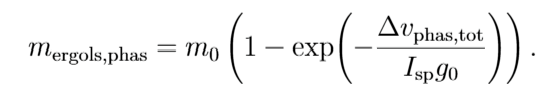

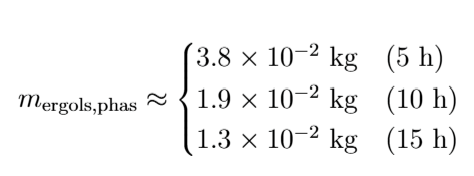

%% --- 5) Durée minimale de phasage utilisable ---
s_arc    = 5e3;             % [m] déphasage le long de l'orbite
Delta_nu = s_arc / r2;      % [rad] erreur d'anomalie vraie

Tcorr_min = Delta_nu / n2;  % [s] durée minimale (n_p > 0)
fprintf('Tcorr_min = %.3f s  (%.6f h)\n\n', Tcorr_min, Tcorr_min/3600);

Tcorr_min = 0.703 s  (0.000195 h)



dV1 = vP_T - v1;

Unrecognized function or variable 'vP_T'.

dV2 = v2   - vA_T;
dVtot = dV1 + dV2;
dVtot_H = dVtot;       % ou dVtot_H = dV1 + dV2;

%% --- Préparation : stratégie 1 (référence) ---
% Masse consommée pour le Hohmann (stratégie 1)
mf_H      = m0 * exp(-dVtot_H/(Isp*g0));   % masse après Hohmann
m_prop_H  = m0 - mf_H;                     % ergols stratégie 1
v2        = sqrt(mu/r2);                   % vitesse circulaire orbite haute

fprintf('Stratégie 1 (Hohmann seul) :\n');
fprintf('  dV_Hohmann total = %.3f m/s\n', dVtot_H);
fprintf('  m_prop_Hohmann   = %.3f kg\n\n', m_prop_H);

%% --- 5) et 6) Phasage pour 5 h, 10 h, 15 h ---
Tcorr_vec = [5, 10, 15]*3600;  % [s] durées de phasage
labels    = {'5 h','10 h','15 h'};

fprintf('Stratégie 2 : correction de phasage (cas a : véhicule en avance)\n');

for k = 1:length(Tcorr_vec)
    Tcorr = Tcorr_vec(k);

    % vitesse angulaire et demi-grand axe de l'orbite de phasage (cas a)
    n_p   = n2 - Delta_nu/Tcorr;         % [rad/s]
    a_p   = (mu / n_p^2)^(1/3);          % [m]

    % vitesses au point de manoeuvre (rayon r2)
    v_p   = sqrt(mu*(2/r2 - 1/a_p));     % [m/s]
    dV1   = v_p - v2;                    % première impulsion
    dVtot_phase = 2*abs(dV1);            % 2ème impulsion même module

    % masse d'ergols pour le phasage :
    % on part avec la masse mf_H (après Hohmann)
    m0_phase   = mf_H;
    mf_phase   = m0_phase * exp(-dVtot_phase/(Isp*g0));
    m_prop_phase = m0_phase - mf_phase;

    % masse totale consommée stratégie 2 (Hohmann + phasage)
    m_prop_total_strat2 = m_prop_H + m_prop_phase;

    fprintf('--- Tcorr = %s ---\n', labels{k});
    fprintf('  a_p - r2      = %.2f m\n', a_p - r2);
    fprintf('  dV_phase_tot  = %.5f m/s\n', dVtot_phase);
    fprintf('  m_prop_phase  = %.5f kg\n', m_prop_phase);
    fprintf('  m_prop_tot S2 = %.5f kg (vs S1 = %.5f kg)\n\n', ...
            m_prop_total_strat2, m_prop_H);
end

fprintf('Conclusion : la correction de phasage consomme quelques 10^{-2} kg,\n');
fprintf('soit négligeable devant les ~%.1f kg du transfert de Hohmann.\n', m_prop_H);
fprintf('La stratégie 1 est la plus économe si on peut choisir le départ,\n');
fprintf('la stratégie 2 sert surtout à corriger un petit déphasage après coup.\n');

#### 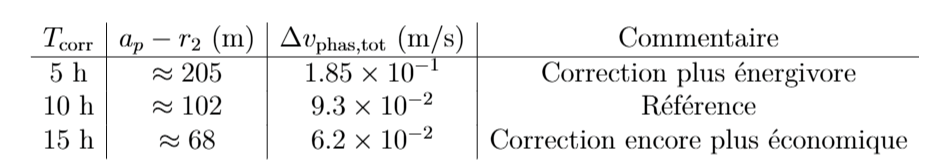

#### **Resumer visuel avec toutes les trajectoires  :**

% orbites circulaires
x1 = r1*cos(theta);    y1 = r1*sin(theta);      % orbite basse
x2 = r2*cos(theta);    y2 = r2*sin(theta);      % orbite haute

%% --- TRANSFERT DE HOHMANN (Partie 1 + stratégie 1) ---
aT   = (r1 + r2)/2;                     % demi-grand axe ellipse transfert
eT   = (r2 - r1)/(r2 + r1);             % excentricité
pT   = aT*(1 - eT^2);

% ellipse de transfert de B (périgée) à A (apogée)
nu = linspace(0,pi,300);
rT = pT ./ (1 + eT*cos(nu));
xT = rT .* cos(nu);
yT = rT .* sin(nu);

% points B (à droite) et A (à gauche)
xB = r1; yB = 0;
xA = -r2; yA = 0;

% temps de transfert
Ttrans = pi*sqrt(aT^3/mu);          % [s]

% vitesse angulaire sur orbite haute (cible)
n2 = sqrt(mu/r2^3);                 % [rad/s]

% trajectoire de la cible pendant le transfert (stratégie 1)
Delta_theta_cible = n2*Ttrans;
nu_c0 = -Delta_theta_cible;         % anomalie initiale
Npts = 200;
theta_cible = linspace(nu_c0, 0, Npts);
xC = r2*cos(theta_cible);
yC = r2*sin(theta_cible);


figure('Name','Stratégie 1 – Hohmann + rendez-vous');
hold on; grid on; axis equal; box on;

% Terre
plot(0,0,'ko','MarkerFaceColor','k','MarkerSize',6);
text(0,0,' Terre','FontSize',11);

% orbites circulaires
plot(x1,y1,'Color',[0 0.45 0.74],'LineWidth',1.4);   % orbite basse
plot(x2,y2,'k','LineWidth',1.4);                     % orbite haute

% ellipse de transfert (traj. véhicule)
plot(xT,yT,'r','LineWidth',2);

% trajet de la cible pendant le transfert
plot(xC,yC,'--','Color',[1 0 1],'LineWidth',2);

% points B, A, cible(t0), rendez-vous
plot(xB,yB,'bo','MarkerFaceColor','b','MarkerSize',7);
text(xB,yB,'  B','Color','b','FontSize',11);

plot(xA,yA,'go','MarkerFaceColor','g','MarkerSize',9);
text(xA,yA,'  Rendez-vous A','Color',[0 0.6 0],...
     'FontSize',11,'FontWeight','bold');

plot(xC(1),yC(1),'ms','MarkerFaceColor','m','MarkerSize',8);
text(xC(1),yC(1),'  Cible(t_0)','Color',[1 0 1],'FontSize',11);

% flèches de delta-v (schéma)
quiver(xB,yB,0,0.12*r1,0,'Color','b','LineWidth',1.8,'MaxHeadSize',1);
text(xB,yB+0.13*r1,'\Delta v_1','Color','b','FontSize',11);

quiver(xA,yA,0,0.12*r2,0,'Color','r','LineWidth',1.8,'MaxHeadSize',1);
text(xA,yA+0.13*r2,'\Delta v_2','Color','r','FontSize',11);

title('Stratégie 1 : Transfert de Hohmann 500 km \rightarrow 1500 km avec rendez-vous');
xlabel('x [m]'); ylabel('y [m]');

legend({'Orbite basse','Orbite haute',...
        'Ellipse de transfert (véhicule)',...
        'Trajectoire cible durant transfert',...
        'Points B et A / Rendez-vous'},...
        'Location','bestoutside','FontSize',10);
s_arc = 5e3;              % déphasage le long de l'orbite [m]
Delta_nu = s_arc / r2;    % erreur angulaire [rad]

Tcorr_vec = [5, 10, 15]*3600;  % [s]

% on va stocker les rayons ~ équivalents de phasage (r = a_p)
r_phase_a = zeros(size(Tcorr_vec)); % cas a : véhicule en avance
r_phase_b = zeros(size(Tcorr_vec)); % cas b : véhicule en retard

for k = 1:length(Tcorr_vec)
    Tcorr = Tcorr_vec(k);

    % cas a : véhicule en avance -> orbite plus haute (n_p < n2)
    n_p_a = n2 - Delta_nu/Tcorr;
    a_p_a = (mu/n_p_a^2)^(1/3);
    r_phase_a(k) = a_p_a;

    % cas b : véhicule en retard -> orbite plus basse (n_p > n2)
    n_p_b = n2 + Delta_nu/Tcorr;
    a_p_b = (mu/n_p_b^2)^(1/3);
    r_phase_b(k) = a_p_b;
end

%% =======================
%  FIGURE 2 : STRATEGIE 2
%% =======================
figure('Name','Stratégie 2 – Orbites de phasage');
hold on; grid on; axis equal; box on;

% orbite haute de référence
plot(x2,y2,'k','LineWidth',1.6);
text(0,0,' Terre','FontSize',11);
title('Stratégie 2 : Correction de phasage (cas a & cas b)');
xlabel('x [m]'); ylabel('y [m]');

colors = lines(3);

for k = 1:length(Tcorr_vec)
    th = linspace(0,2*pi,400);

    % cas a : orbite plus haute
    x_pa = r_phase_a(k)*cos(th);
    y_pa = r_phase_a(k)*sin(th);
    plot(x_pa,y_pa,'--','Color',colors(k,:),'LineWidth',1.4);

    % cas b : orbite plus basse
    x_pb = r_phase_b(k)*cos(th);
    y_pb = r_phase_b(k)*sin(th);
    plot(x_pb,y_pb,'-.','Color',colors(k,:),'LineWidth',1.4);
end

legendEntries = {'Orbite cible (1500 km)', ...
    'Phasage cas a, 5 h', 'Phasage cas b, 5 h', ...
    'Phasage cas a, 10 h','Phasage cas b, 10 h', ...
    'Phasage cas a, 15 h','Phasage cas b, 15 h'};

legend(legendEntries,'Location','bestoutside','FontSize',9);